# Simulating ECG signal

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

### Acknowledgements

This notebook uses modified code ecgsyn written by Patrick McSharry & Gari Clifford based on reference [1]. In order to run the code, please download ECGSSYN_Matlab folder.

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter7/Simulator'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Simulating EGC signal

In this section, we are going to simulate ECG signal based on [1].

addpath('ESGSYN_Matlab');

[s, ipeaks,rr0] = ecgsyn(250,20,0.1,46,1,0.5,250); % sampling rate 250, number of pulses 20, noise 0.1, HR 60, LF/HF =0.5 

ECG sampled at 250 Hz
Approximate number of heart beats: 20
Measurement noise amplitude: 1.000000e-01 
Heart rate mean: 46 bpm
Heart rate std: 1 bpm
LF/HF ratio: 0.5
Internal sampling frequency: 250
      P  Q  R  S  T
ti = [-1.14321 -0.22923 0 0.22923 1.63316] radians
ai = [1.2 -5 30 -7.5 0.75]
bi = [0.218899 0.0875595 0.0875595 0.0875595 0.350238]
Integrating dynamical system


d = 4

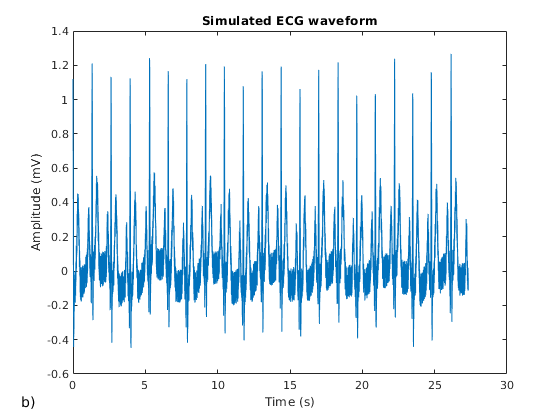

% Plotting
T=1/250;
t1=(0:length(s)-1)*T;
end1=6831; % for 27 sec
figure
plot(t1(1:end1),s(1:end1))
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('Simulated ECG waveform');
annonation_save('b)',"Fig7.4b.jpg", SAVE_FLAG);

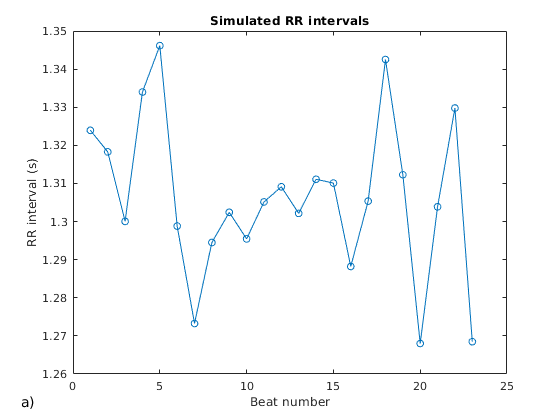


% Plotting
figure
i=1:23;
plot(i, rr0(i),'o-')
xlabel('Beat number');
ylabel('RR interval (s)');
title('Simulated RR intervals');
annonation_save('a)',"Fig7.4a.jpg", SAVE_FLAG);

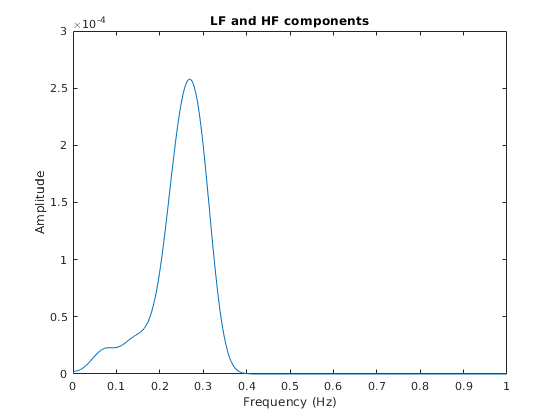


figure
rr2 = interp(rr0-mean(rr0),10);
[p,f] = pspectrum(rr2,10);
plot(f,abs(p))
xlim([0,1])
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('LF and HF components');

## References

[1] P.E. McSharry, G.D. Clifford, L. Tarassenko, and L.A. Smith, "Dynamical Model for Generating SyntheticElectrocardiogram Signals," IEEE TRANSACTIONS ON BIOMEDICAL ENGINEERING, VOL. 50, NO. 3, MARCH 2003 